# **Esercitazione 3 - EMG**

8 prove in 4 condizioni diverse.

Condizione 1 (prove 1 e 2): i soggetti dovevano compiere movimenti piccoli e lenti.

Condizione 2 (prove 3 e 4): movimenti piccoli e veloci.

Condizione 3 (prove 5 e 6): movimenti grandi e lenti.

Condizione 4 (prove 7 e 8): movimenti grandi e veloci.

load("emg_data.mat")

%time
[num_casi, num_soggetti]= size (emg_data);

%prealloco cell array
time = cell (num_casi, num_soggetti);

for index_soggetto = 1: num_soggetti
for index_caso = 1: num_casi
    
   signal = cell2mat(emg_data(index_caso, index_soggetto));
   time {index_caso, index_soggetto} = signal(:,1);
end
end

*Obiettivo 1: Estrarre l’inviluppo del segnale EMG per ogni soggetto per ogni prova. *

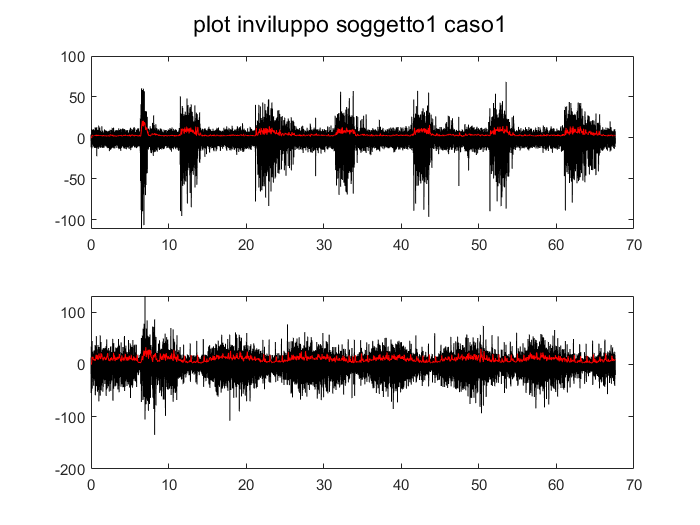

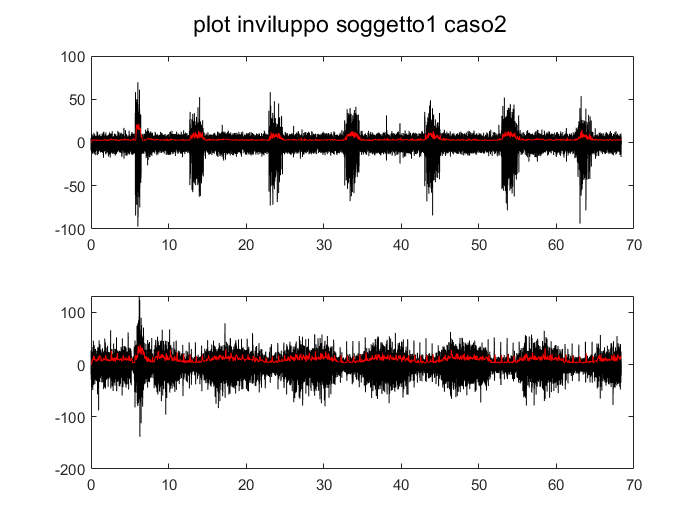

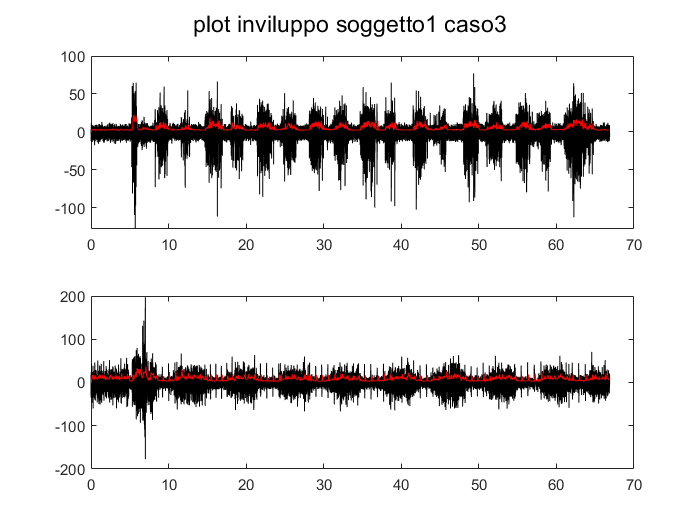

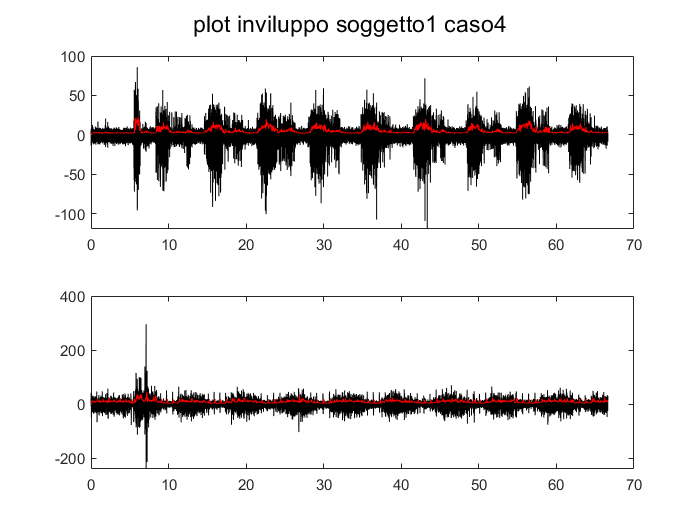

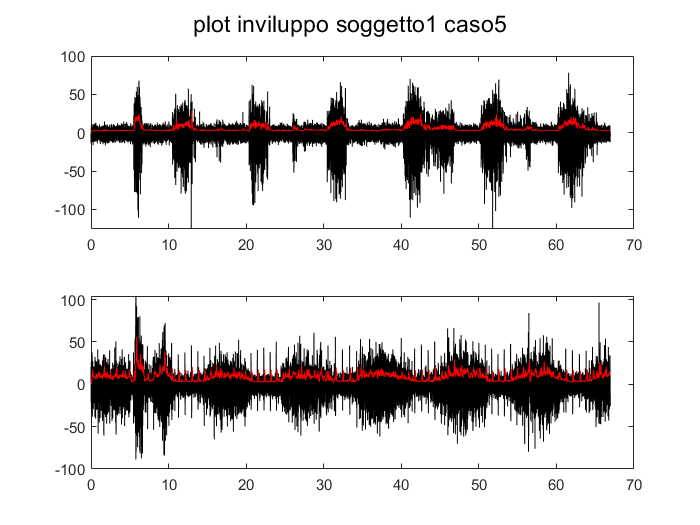

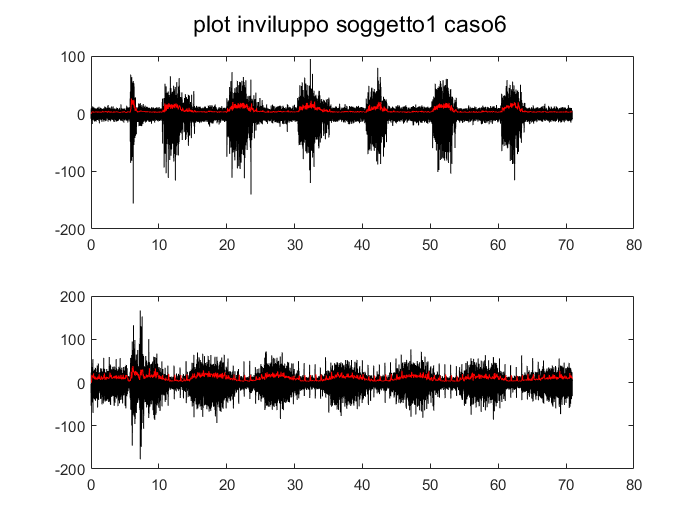

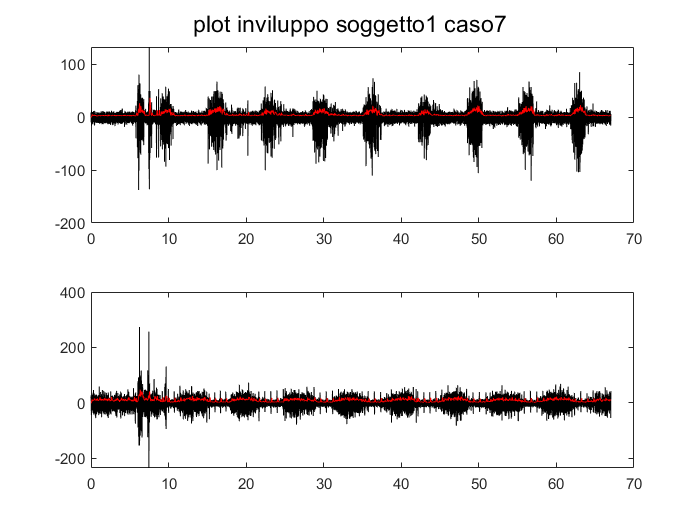

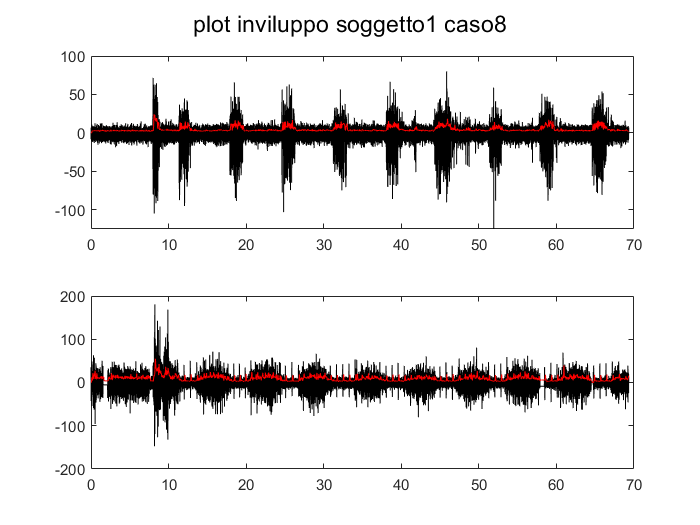

%uso della funzione get_envelope() 

fs = 2000;
nfft= 2048;

inviluppo = get_envelope (emg_data, fs, nfft);

*Obiettivo 2: Normalizzazione del segnale EMG rispetto al massimo valore di ogni soggetto. *

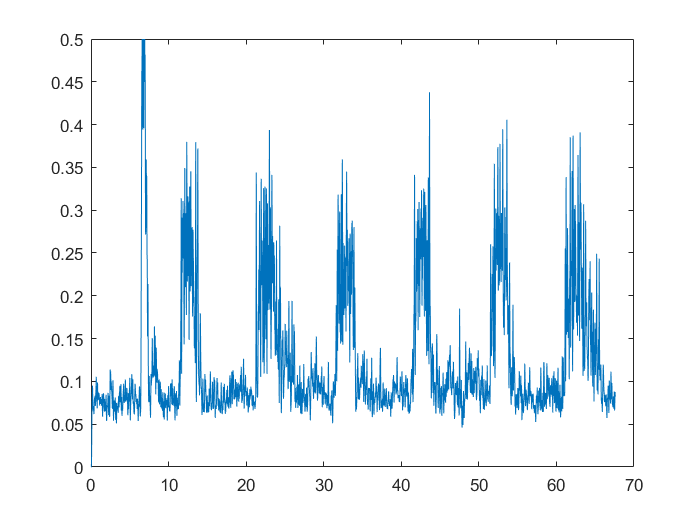

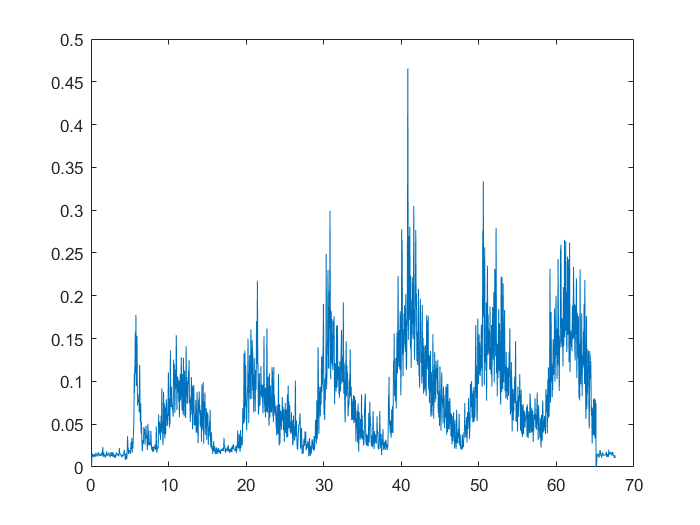

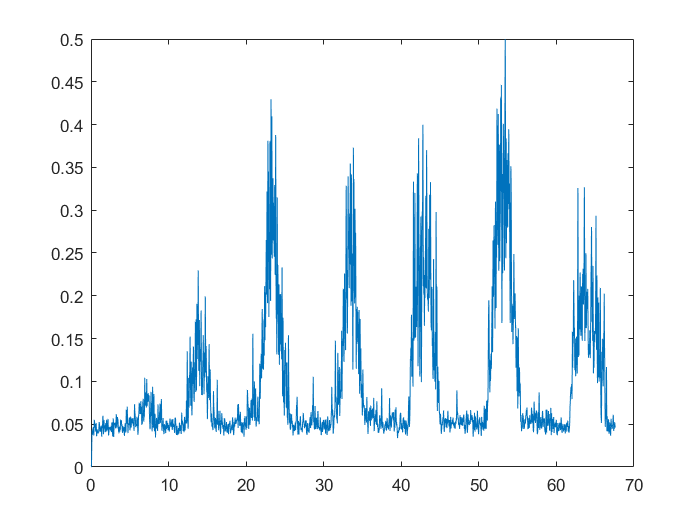

%uso funzione data_normalization()
signal = cell2mat(emg_data(1, 1));
time = signal(:,1);
norm=data_normalization(inviluppo, time); 

*Obiettivo 3: Calcolare lo spettro medio per ogni soggetto per ogni muscolo.*

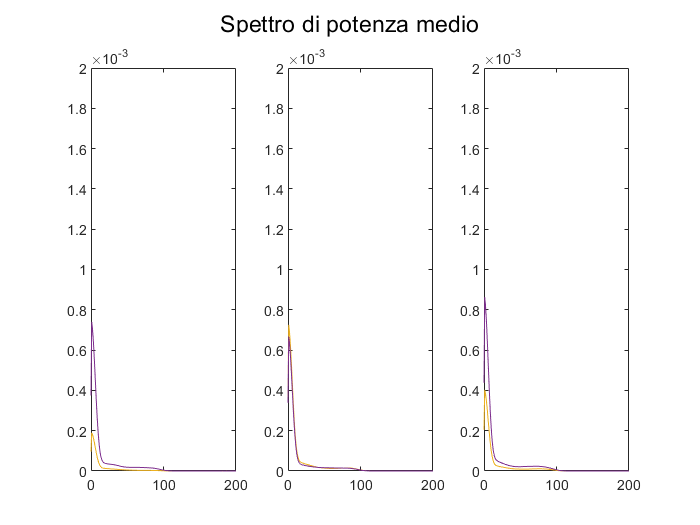

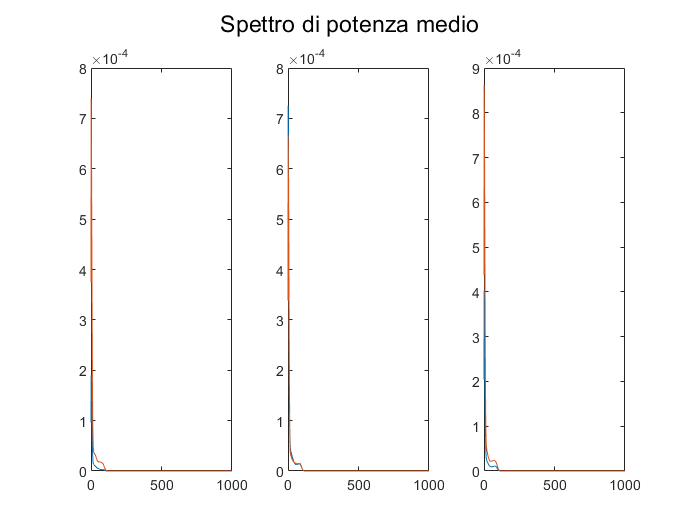

overlap=100;
window=200;

%utilizzo funzione meanpsd() per il calcolo e la visualizzazione dello
%spettro di potenza medio di ciascun muscolo di ogni soggetto
meanpsd(norm,overlap,window,nfft,fs);

*Obiettivo 4: Trovare le attivazioni per ogni soggetto e per ogni prova.*

%uso funzione detect_activation()

[peaks,time_peaks]=detect_activation(norm, time, 0.5);       

*Obiettivo 5: Visualizzazione delle singole attivazioni nelle 4 condizioni.*

...

*Obiettivo 6: calcolare e visualizzare la durata di attivazione media per ogni soggetto e per ogni prova.*

uso full_width at half maximum

...

*Obiettivo 7: Effettuare un permutation test sui dati tramite l'utilizzo di una funzione.*

%uso funzione my_permutation_test()